% Assuming a total of 2 sensors
% Assuming a 90% attack probability on the first sensor and a 10% attack probability on the second sensor
% Assuming that the time of each scene is 50 and the service time of the sensor is 5, that is, there are given 10 scheduling schemes in each scene
% Firstly, assume the error caused by a completely random sensor selection scheme
% 
clc;clear;
tic

% rng('default')


N = 2;
% Assume the number of sensors is N
N_i = [1,1];
% Assume the dimension of each sensors is N_i

M = 1;
% Suppose we choose M sensors in each step

T = 10;
% Assume the total time is T

Trust = 0.5 * ones(1,N);
% Trust value initialization

Cpu = 1;

ki_i = 0;

alpha = 0.99;
epsilon = 0.99;

% Generate the mathix batch by batch. I use eval function here before I
% find a better way to solve this problem.
% eval function has two obvious disadvantage:
% 1. it is very ugly and hard to read
% 2. opration times of eval function is very slow

states_number = T;
% State number
action_number = nchoosek(N,M);
% Action numbet
Q_table = zeros(action_number, states_number);



test_round = 1;
% test rounds

test_number = 1;
% test number. As there is some problems with dqn, I only design 5
% experiments here

Reward_all = zeros(test_number, test_round);
% How to evaluate the strategies? I use Reward_all.
% Each line stardards an experments and it can be updated with time.


%%%%%%%%%% generate corr_comb_num
corr_comb_num = zeros(nchoosek(N,M),M+1);
for i = 1:nchoosek(N,M)
    corr_comb_num(i,1) = i;
end
while ~isempty(find(corr_comb_num == 0))
    tmp = randperm(N);
    p = tmp(1:M);
    p = sort(p);
    out = comb2num(p,N,M);
    corr_comb_num(out,2:M+1) = p;
end
corr_comb_num;
% Some very strange methods are used to obtain the one-to-one correspondence between
% the serial number of combination number and combination, which is stored
% in corr_comb_num
%%%%%%%%%% end generate corr_comb_num



states_number = T;
% State number
action_number = nchoosek(N,M);
% Action numbet
Q_table = zeros(action_number, states_number);



%%%%%%%%%% start generate A_i, Q_i, C_i and R_i
% These four do not change with times
for i = 1:N
    eval(["A_" + num2str(i) + " = eye(N_i(i), N_i(i)) * (0.99);"]);
end
% Fixing A_i matrix
% Here A_i doesn't change when t changes. Actually it changes easily.

for i = 1:N
    eval(["Q_" + num2str(i) + " = eye(N_i(i))/10000;"]);
end
% Fixing error matrix Q_i

for i = 1:N
    eval(["C_" + num2str(i) + " = eye(N_i(i), N_i(i)) * (1 );"]);
end
% Fixing C_i matrix

for i = 1:N
    eval(["R_" + num2str(i) + " = eye(N_i(i))/10000;"]);
end
% Fixing error matrix R_i
%%%%%%%%%% end generate A_i, Q_i, C_i and R_i

P_record = zeros(1,6);

Trust_score = zeros(test_round,T,N)

Trust_score = Trust_score(:,:,1) =

     0     0     0     0     0     0     0     0     0     0


Trust_score(:,:,2) =

     0     0     0     0     0     0     0     0     0     0




for test_times = 1:test_round
    % generate data again
    % rng(test_times * 10)
    % randomly choose seeds

    %%%%%%%%%% start generate error matrix, X_i and Y_i
    % These change with times
    for i = 1:N
        eval(["X_" + num2str(i) + " = zeros(N_i(i), T);"]);
    end
    for i = 1:N
        eval(["X_" + num2str(i) + "(:, 1) = ones(size(X_" + num2str(i) + "(:, 1)));"]);
    end
    % Initialize X_i matrix

    for i = 1:N
        for t = 1:T
            eval(["omega_" + num2str(i) + "_" + num2str(t) + " = zeros(N_i(i), N_i(i));"]);
            for k = 1:N_i(i)
                eval(["omega_" + num2str(i) + "_" + num2str(t) + "(k,k) = mvnrnd(0, Q_" + num2str(i) + "(N_i(i),N_i(i)));"]);
            end
        end
    end
    % Generate omega_i_t according to Q_i

    for i = 1:N
        eval(["Y_" + num2str(i) + " = ones(N_i(i), T);"]);
    end
    %     for i = 1:N
    %         eval(["Y_" + num2str(i) + "(:, i) = ones(size(Y_" + num2str(i) + "(:, 1))) *  (1);"]);
    %     end
    % Initialize Y_i matrix

    for i = 1:N
        for t = 1:T
            eval(["nu_" + num2str(i) + "_" + num2str(t) + " = zeros(N_i(i), N_i(i));"]);
            for k = 1:N_i(i)
                eval(["nu_" + num2str(i) + "_" + num2str(t) + "(k,k) = mvnrnd(0, R_" + num2str(i) + "(N_i(i),N_i(i)));"]);
            end
        end
    end
    % Generate nu_i_t according to R_i



    reward = 0;

    for i = 1:N
        eval(["P_" + num2str(i) + "_estimate = zeros(N_i(i),N_i(i));"]);
        % Initialize P_i_estimate matrix

        eval(["X_" + num2str(i) + "_estimate = zeros(1,1);"]);
        eval(["Y_" + num2str(i) + "_estimate = zeros(1,1);"]);
        % generate X_i_estimate and Y_i_estimate
    end

    %%%%%%%%%% Strategy1: total random
    reward = 0;

    for i = 1:N
        eval(["X_" + num2str(i) + "_estimated = zeros(1,T-1);"]);
        eval(["P_" + num2str(i) + "_estimated = zeros(1,T-1);"]);
    end


    for t = 1:T-1

        for i = 1:N
            for n = 1:N_i(i)
                eval(["X_" + num2str(i) + "(n, t+1) = A_" + num2str(i) + "(n,:)* X_" + num2str(i) + "(:, t) + omega_" + num2str(i) + "_" + num2str(t) + "(n,n);"]);
            end
        end
        % Calculate X_i according to delay matrix

        for i = 1:N
            eval(["Y_" + num2str(i) + "(:, t+1) = C_" + num2str(i) + " * Y_" + num2str(i) + "(:, t) + nu_" + num2str(i) + "_" + num2str(t) + " * ones(N_i(i),1);"]);
        end
        % Calculate Y_i according to X_i


        % Then we calculate reward and update Q_table

        trust_score = zeros(1,N);

        for i = 1:N
            eval(["Y_thisstep(i) = Y_" + num2str(i) + "(:, t);"]);
        end

        for i = 1:2
            trust_score(i) = 1;
            if t >= 2 && i == 1
                if Trust[i] >= 0.5 
                    trust_score(i) = 1;
                else
                    trust_score(i) = 0;
                end
            end
        end

        for i = 1:N

            % eval(["[P_" + num2str(i) + ",X_" + num2str(i) + "_estimate] = Kalman_filter3(P_" + num2str(i) + "_estimate ,N_i(i) ,X_" + num2str(i) + "_estimate ,Y_" + num2str(i) + "(:, t), A_" + num2str(i) + ", C_" + num2str(i) + ", Q_" + num2str(i) + ", R_" + num2str(i) + ");"]);

            if trust_score(i) == 0
                eval(["P_" + num2str(i) + " = A_" + num2str(i) + " * P_" + num2str(i) + "_estimate * A_" + num2str(i) + "'+ Q_" + num2str(i) + ";"]);
                eval(["P_" + num2str(i) + "_estimate = P_" + num2str(i) + ";"]);
                eval(["X_" + num2str(i) + "_estimate = X_" + num2str(i) + "_estimated(1,t-1);"]);
            else

                eval(["x_" + num2str(i) + "_predicted = A_" + num2str(i) + " * X_" + num2str(i) + "_estimate;"]);
                eval(["P_" + num2str(i) + "_predicted = A_" + num2str(i) + " * P_" + num2str(i) + "_estimate * A_" + num2str(i) + "' + Q_" + num2str(i) + ";"]);
                % update
                eval(["K_new = (P_" + num2str(i) + "_predicted * C_" + num2str(i) + "') / (C_" + num2str(i) + " * P_" + num2str(i) + "_predicted * C_" + num2str(i) + "' + R_" + num2str(i) + ");"]);
                eval(["X_" + num2str(i) + "_estimate = x_" + num2str(i) + "_predicted + K_new * (Y_" + num2str(i) + "(:, t) - C_" + num2str(i) + " * x_" + num2str(i) + "_predicted);"]);
                eval(["P_" + num2str(i) + "_estimate = (eye(N_i(i), N_i(i)) - K_new * C_" + num2str(i) + ") * P_" + num2str(i) + "_predicted;"]);
                % estimate
            end


            eval(["X_" + num2str(i) + "_estimated(1,t) = X_" + num2str(i) + "_estimate;"]);
            eval(["P_" + num2str(i) + "_estimated(1,t) = P_" + num2str(i) + "_estimate;"]);
            % Update P_old_i
        end
        
        for i = 1:2
            Trust(1) = 1/4 * Trust(1) + 1/4 * 1 + 1/4 * 0.9 + 1/4 * X_1_estimated(1,t) / X_1_estimated(1,1) / 3;
            Trust(2) = - 1/4 * Trust(2) + 1/4 * 1 + 1/4 * 0.9 - 1/4 * X_2_estimated(1,t) / X_1_estimated(1,1) / 3;
        end

        Trust_score(test_times,t,:) = Trust;

        % Update P_i according to action



        for i = 1:N
            eval(["reward = reward + (X_" + num2str(i) + "_estimate - X_" + num2str(i) + "(:,t+1))^2;"]);
        end
        % Calculate reward

    end
    Reward_all(1,test_times) =  reward;
    P_record(1) = P_record(1) + P_1_estimate ;
    %%%%%%%%%% end Strategy1
end

ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1


ans = logical
   1



Y_1

Y_1 =     1.0000    0.9885    0.9940    1.0097    0.9927    0.9882    0.9874    0.9675    0.9759    0.9717


Y_2

Y_2 =     1.0000    0.9961    1.0002    0.9888    0.9825    0.9708    0.9747    0.9878    0.9818    0.9862



X_1

X_1 =     1.0000    0.9783    0.9589    0.9428    0.9210    0.9091    0.8910    0.8793    0.8658    0.8531


X_2

X_2 =     1.0000    1.0023    0.9984    0.9890    0.9645    0.9386    0.9095    0.9265    0.9269    0.9202



X_1_estimated

X_1_estimated =     0.5000    0.7903    0.9122    0.9687    0.9798    0.9812    0.9813    0.9690    0.9695


X_2_estimated

X_2_estimated =     0.5000    0.7949    0.9177    0.9579    0.9694    0.9665    0.9679    0.9764    0.9760



P_1_estimated

P_1_estimated = 	1.0e+-4 *

    0.5000    0.5984    0.6134    0.6156    0.6159    0.6159    0.6159    0.6159    0.6159


P_2_estimated

P_2_estimated = 	1.0e+-4 *

    0.5000    0.5984    0.6134    0.6156    0.6159    0.6159    0.6159    0.6159    0.6159



figure
err1 = (X_1(2:end) - X_1_estimated).^2

err1 =     0.2287    0.0284    0.0009    0.0023    0.0050    0.0081    0.0104    0.0106    0.0136


plot(err1,"r")
hold on
err2 = (X_2(2:end) - X_2_estimated).^2

err2 =     0.2523    0.0414    0.0051    0.0000    0.0010    0.0033    0.0017    0.0024    0.0031


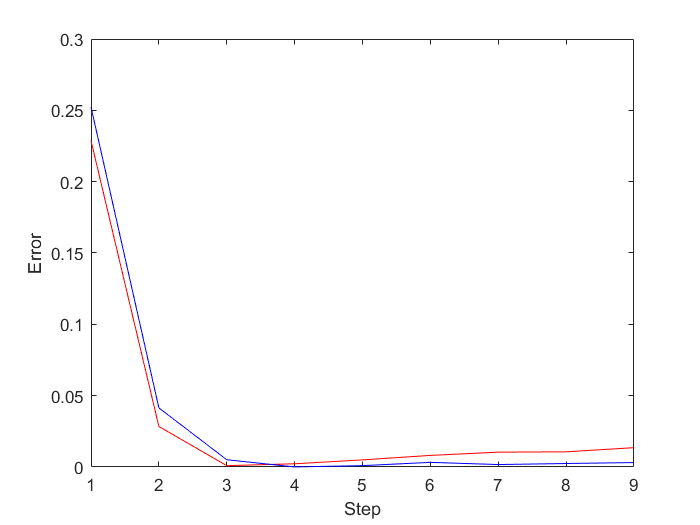

plot(err2,'b')
hold off
ylabel("Error")
xlabel("Step")

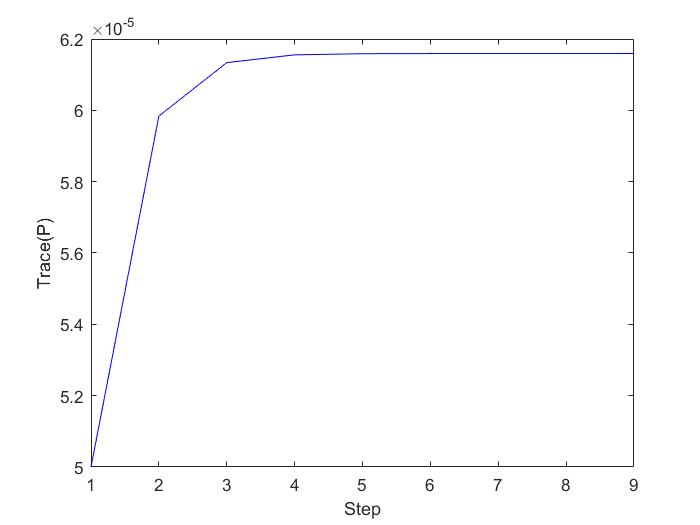


plot(P_1_estimated,"r")
hold on
plot(P_2_estimated,'b')
hold off
ylabel("Trace(P)")
xlabel("Step")

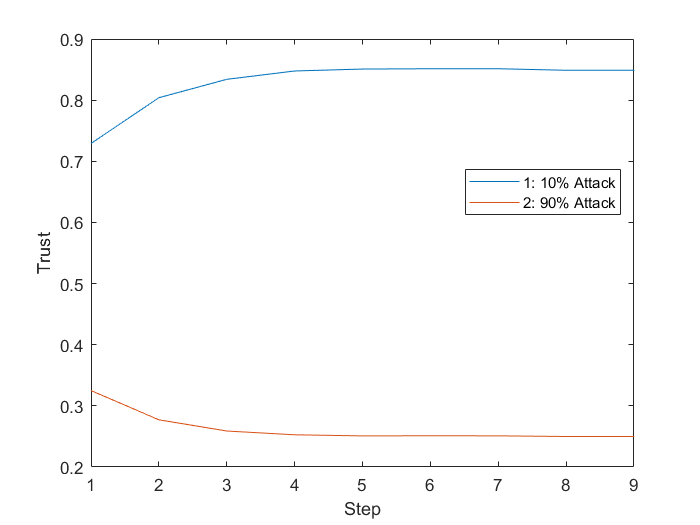



plot(Trust_score(:,:,1))
hold on 
plot(Trust_score(:,:,2))
xlim([1,9])
hold off
ylabel("Trust")
legend('1: 10% Attack','2: 90% Attack')
legend("location","best")
xlabel("Step")